# Script to process load cell data from the M1 vibration testbed

Get load cell (LC) to rigid-body forces convertion matrix

[~, T1] = get_lc_dt();

Permutation matrix to get the correct LC ordering

H = zeros(6);
ord_ind = [4;6;3;1;5;2];
for i1=1:6, H(i1,ord_ind(i1)) = 1; end

Incorporate the permutaion into the convertion

T_lc2rbmF = T1*H;

Load LC data

data_folder = "/Users/rromano/Workspace/gmt-data/AHU-vib-data";
dt_filename1 = "AHU from 0 to 1400 RPM.xlsx";
dt_filename2 = "AHU from 0 to 1400 RPM (60 Hz Filter).xlsx";
dt_filename3 = "AHU from 1400 to 0 RPM (60 Hz Filter).xlsx";
dt_filename4 = "Stiff AHU from 0 to 1400 to 0 RPM (no filters).csv";
dt_filename = dt_filename2;

str = extractBefore(dt_filename,'.');
if (strlength(str) <= 32), Sheet = str;
else, Sheet = extractBefore(str,min(32,strlength(str))); 
end

Range = "B25:I23795";
try
    lc_dt = readmatrix(fullfile(data_folder,dt_filename),"Sheet",Sheet,"Range",Range);
    dt_suffix = " - with isolator";
catch
    Range = "B25:I137674";
    lc_dt = readmatrix(fullfile(data_folder,dt_filename),"Range",Range);
    dt_suffix = " - stiff config";
end

Sampling period (pre-defined)

Ts = 1e-3;

Relevant range

i1 = 15/Ts + 1;     % Starting sample
i2 = 23/Ts;         % Ending sample

## LC measurement time-domain plot 

t = Ts*((1:size(lc_dt,1)) -1);
subplot(2,1,1)
plot(t(i1:i2),lc_dt(i1:i2,1:6));
ylabel('LC measurement (N)');
grid on;
subplot(2,1,2)
plot(t(i1:i2),lc_dt(i1:i2,7:8))
grid on;
ylabel('Fan speed (rpm)'); xlabel('Time (s)')
legend('Set-point','Actual (Tacho meas)',...
    'Orientation',"horizontal","Location","best")
legend boxoff

## AHU rigid-body forces: time-domain plot

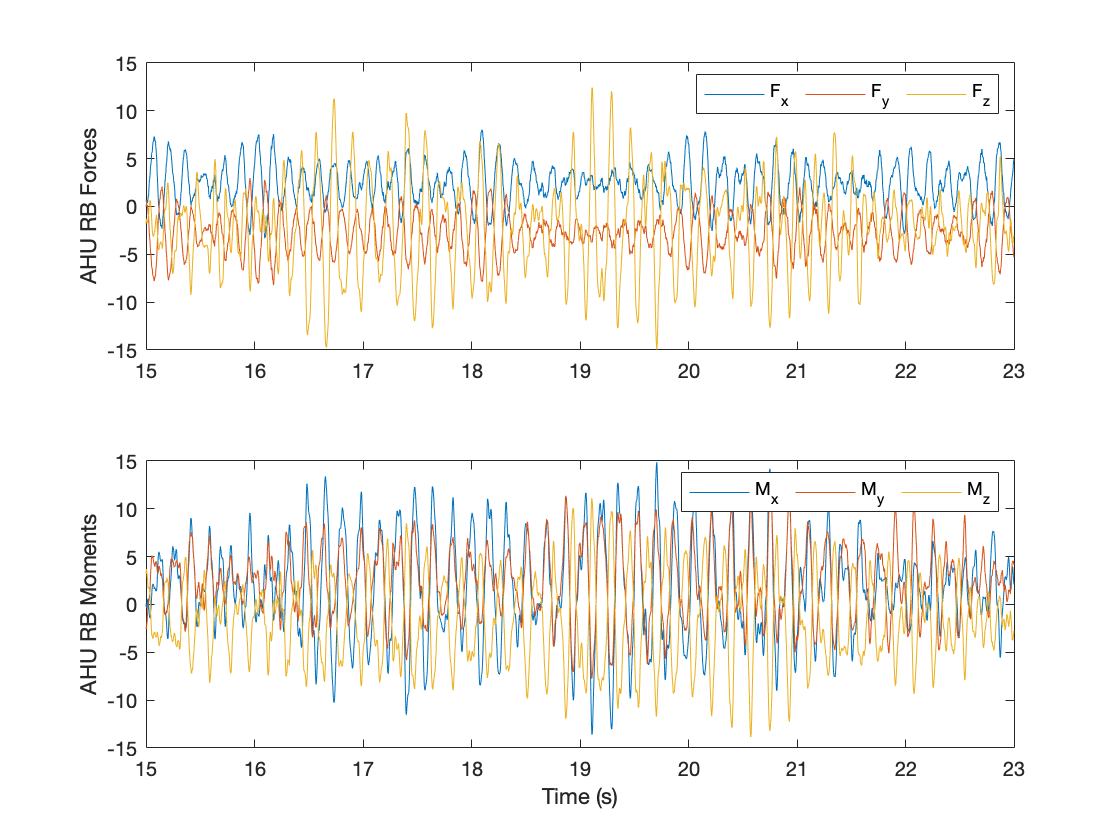

figure
ahu_f = (T_lc2rbmF * lc_dt((i1:i2),1:6)')';
subplot(2,1,1)
plot(t(i1:i2),ahu_f(:,1:3));
ylabel('AHU RB Forces');
legend('F_x','F_y','F_z','Orientation',"horizontal")
subplot(2,1,2)
plot(t(i1:i2),ahu_f(:,4:6));
ylabel('AHU RB Moments'); xlabel('Time (s)')
legend('M_x','M_y','M_z','Orientation',"horizontal")

## AHU PSD

Welch algorithm settings

nFFT = 2048;
M = nFFT/2; %1024;
psdAHUf = zeros(nFFT/2 + 1,6);

Rigid-body force PSD computation (welch method)

for ik = 1:6
    [psdAHUf(:,ik),freq] = utils.pwelch(ahu_f(:,ik),2*M,[],nFFT,1/Ts,'onesided');%,'no-strip');
end

Plot spectra

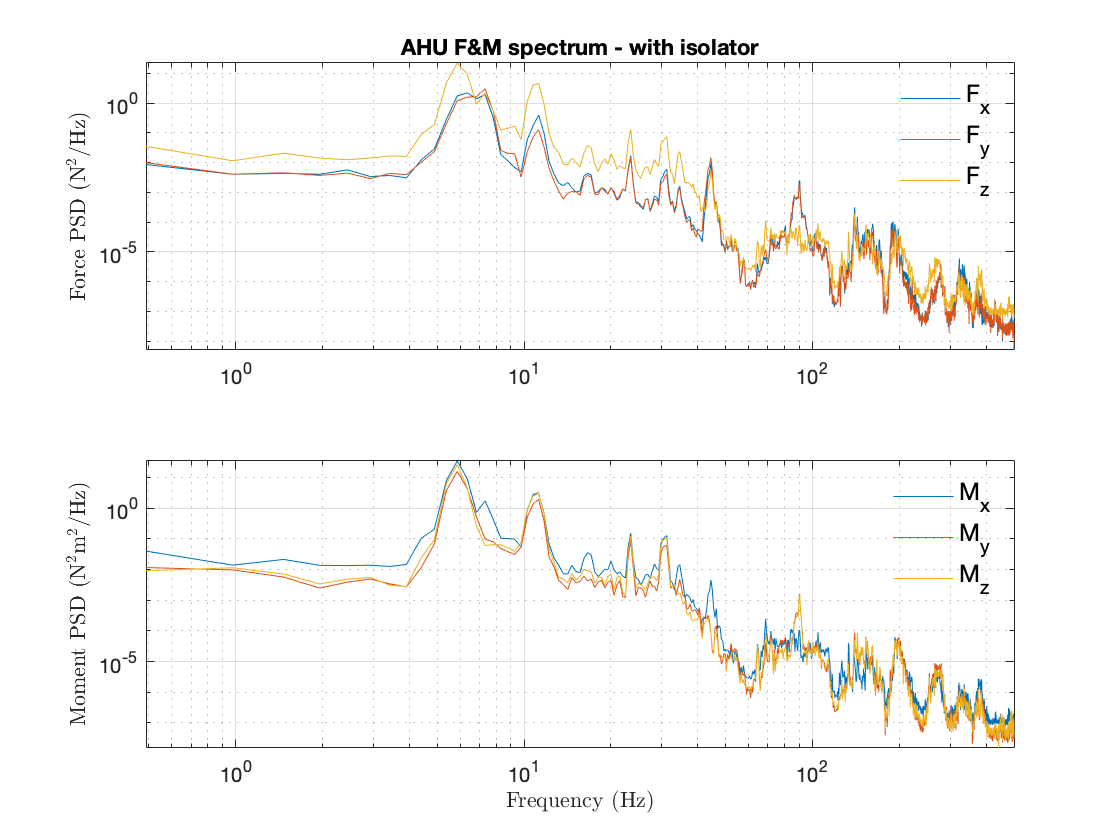

figure
subplot(2,1,1);
for ik=1:3
    loglog(freq,psdAHUf(:,ik));
    hold on;
end
legend('F_x','F_y','F_z','Fontsize',12); legend boxoff
ylabel('Force PSD ($\textrm{N}^2/\textrm{Hz}$)','Interpreter','latex');
grid on; hold off; axis tight;
title("AHU F&M spectrum"+dt_suffix)
subplot(2,1,2);
for ik=4:6
    loglog(freq,psdAHUf(:,ik));
    hold on;
end
legend('M_x','M_y','M_z','Fontsize',12); legend boxoff
ylabel('Moment PSD ($\textrm{N}^2\textrm{m}^2/\textrm{Hz}$)','Interpreter','latex');
grid on; hold off; axis tight;
xlabel('Frequency (Hz)','Interpreter','latex');

Cumulative AHU vibration load PSD

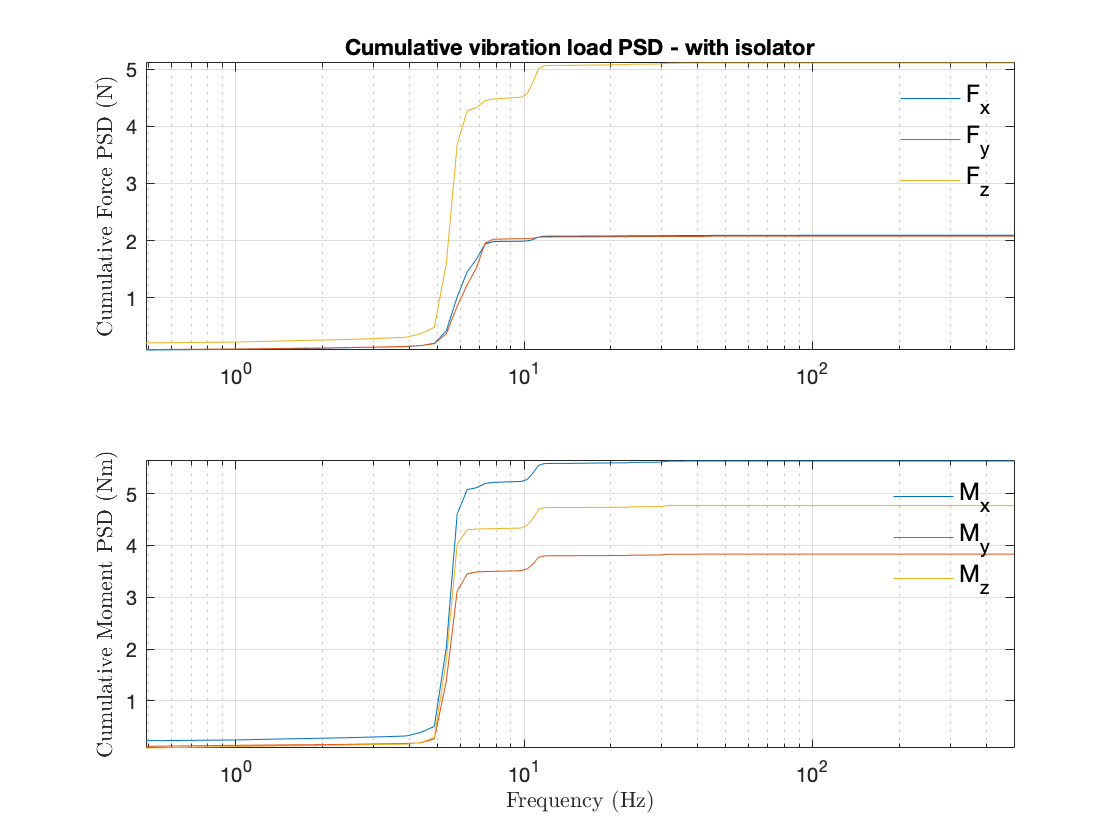

figure
DeltaFs = diff(freq(1:2));
aux_cpsd = zeros(6,1);
for i1 = 1:3
    subplot(211); aux = sqrt(DeltaFs*cumsum(psdAHUf(:,i1)));
    semilogx(freq, aux); hold on;
    aux_cpsd(i1) = aux(end);
end
title("Cumulative vibration load PSD"+dt_suffix);
hold off; grid on; axis tight;
legend('F_x','F_y','F_z','Fontsize',12); legend boxoff
ylabel('Cumulative Force PSD ($\textrm{N}$)','Interpreter','latex');
for i1 = 4:6
    subplot(212); aux = sqrt(DeltaFs*cumsum(psdAHUf(:,i1)));
    semilogx(freq, aux); hold on;
    aux_cpsd(i1) = aux(end);
end
ylabel('Cumulative Moment PSD ($\textrm{Nm}$)','Interpreter','latex');
legend('M_x','M_y','M_z','Fontsize',12); legend boxoff
hold off; grid on; axis tight;
xlabel('Frequency (Hz)','Interpreter','latex');


fprintf("AHU load (%s):\n\tFx/Mx\t Fy/My\t Fz/Mz\n"+...
    "\t%.3gN\t %.3gN\t %.3gN\n\t%.3gNm\t %.3gNm\t %.3gNm",...
    dt_suffix, aux_cpsd');

AHU load ( - with isolator):
	Fx/Mx	 Fy/My	 Fz/Mz
	2.09N	 2.08N	 5.11N
	5.63Nm	 3.83Nm	 4.77Nm

fprintf("AHU load:\n\tFx/Mx\t Fy/My\t Fz/Mz\n"+...
    "\t%.3gN\t %.3gN\t %.3gN\n\t%.3gNm\t %.3gNm\t %.3gNm",aux_cpsd');

AHU load:
	Fx/Mx	 Fy/My	 Fz/Mz
	2.09N	 2.08N	 5.11N
	5.63Nm	 3.83Nm	 4.77Nm

Save AHU vibration load PSD

if(false)
    psd_filename = "ahu_psd_1KHz_1400rpm.mat"; %#ok<*UNRCH> 
    save(psd_filename,"psdAHUf","freq");
    fprintf("\nAHU PSD saved as %s", psd_filename);
end

Save AHU vibration forces and moments

if(false)
    ahu_tdom_filename = "ahu_tdom_1KHz_1400rpm.mat";
    t_range = [i1; i2];
    ahu_f = (T_lc2rbmF * lc_dt(:,1:6)')';
    save(ahu_tdom_filename,"ahu_f","t_range");
    fprintf("\nAHU load time-series saved as %s", ahu_tdom_filename);
end

## Auxiliary functions

Function defining the load cell attachment points and the LC to rigid-body forces conversion matrix.

function [nodexyz, T1] = get_lc_dt()
nodexyz = [468.1294683	-19.12730746	260.2143552;...
    409.4896035	14.7284343	308.0858232;...
    250.6294683	-395.8483581	260.2143552;...
    191.9896035	-361.9926164	308.0858232;...
    217.5	347.2641821	308.0858232;...
    217.5	414.9756656	260.2143552;...
    -217.5	347.2641821	308.0858232;...
    -217.5	414.9756656	260.2143552;...
    -409.4896035	14.7284343	308.0858232;...
    -468.1294683	-19.12730746	260.2143552;...
    -191.9896035	-361.9926164	308.0858232;...
    -250.6294683	-395.8483581	260.2143552];

meanz = mean(nodexyz(:,3));
midp = [0,0,meanz]';
T = zeros(6);
for k =1:2:12
    ii = (k-1)/2+1;
    xyz = nodexyz(k+1,:)-nodexyz(k,:);
    if(xyz(3)<0)
        xyz = -xyz;
    end
    R = 1e-3*((nodexyz(k+1,:)'+nodexyz(k,:)')/2-midp); %APPROXIMATE moment arm... need to decide on a CENTER
    T(:,ii) = [xyz'/norm(xyz); cross(R,xyz'/norm(xyz))];    
end

T1 = inv(T);
end